## Newton_method 

### Input

f = @(x) 2^x - 5*x +2;  % the function
df = @(x) log(2)*(2^x)-5;   % derivative of function
x0 = 0;                % first interval
n = 2;                 % no of iterations
e=10^-4;                % tolerance

### algebraic Eq. $2^x -5x+2$

if df(x0)~=0
    for i=1:n
        x1 = x0 -f(x0)/df(x0);
        fprintf('x%d = %.20f\n',i,x1)
        if abs (x1-x0)<e
            break
        end
        if df(x1) == 0
            disp('Newton failed')
        end
        x0 = x1;
    end
else
    disp('Newton failed');
end

x1 = 0.69656431871986701498
x2 = 0.73211534565952418596


### Visualization

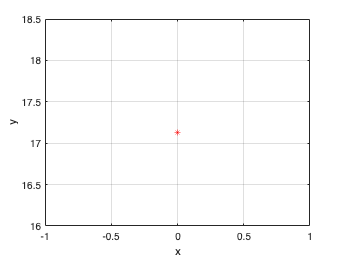

plot(a(i),b(i),'r*'); grid on;
xlabel('x'); ylabel('y');
hold on;